clear

% Read img file
img = imread("../db/DB1/db1_07.jpg")

img = 592×398×3 uint8 array
img(:,:,1) =

   193   193   193   174   147   124   147   183   195   189   179   188   191   193   186   190   185   186   195   183   179   187   183   188   189   186   190   186   187   186   191   187   190   191   191   187   181   182   183   180   193   191   190   188   189   190   190   189   190   185   188   187   191   188   192   189   192   195   187   186   185   180   186   189   190   190   191   192   192   190   190   192   188   190   200   194   192   191   197   190   166   187   186   186   184   170   169   181   172   183   147   143   213   162   192   179   130   172   186   180   160   200   178   201   200   195   158   116   127   147   160   171   172   194   150   132   144   133   161   128   130   121   119    74    59    83    60    99    96   108   102   134   123    74    92    90    70    47    27    65    39    42    32    33    27    39    44    65    64    71    83    68    55    63    62    59    50    60    64    

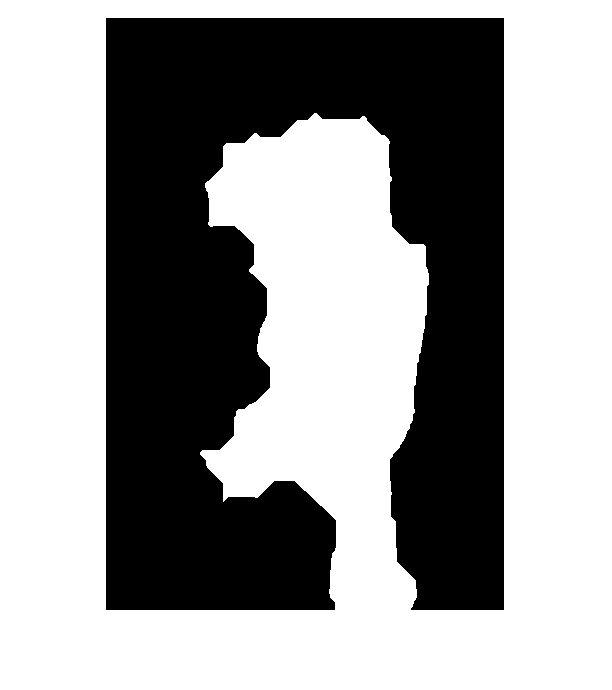


% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)


%Find eyes and a mouth
eyes = eyemap(img_gw)

eyes =     0.1298    0.1286    0.1294    0.1284    0.1284    0.1256    0.1261    0.1264    0.1303    0.1303    0.1311    0.1307    0.1331    0.1322    0.1312    0.1113    0.0932    0.0932    0.0934    0.0932    0.0929    0.0932    0.0926    0.0920    0.0929    0.0920    0.0923    0.0896    0.0896    0.0896    0.0898    0.0896    0.0898    0.0921    0.0921    0.0918    0.0909    0.0918    0.0903    0.0900    0.0911    0.0911    0.0916    0.0908    0.0908    0.0916    0.0916    0.0908    0.0878    0.0875
    0.1294    0.1286    0.1311    0.1281    0.1281    0.1265    0.1263    0.1276    0.1295    0.1303    0.1315    0.1319    0.1338    0.1352    0.1304    0.1109    0.0932    0.0932    0.0932    0.0934    0.0926    0.0934    0.0923    0.0926    0.0929    0.0920    0.0923    0.0920    0.0896    0.0896    0.0898    0.0896    0.0915    0.0915    0.0909    0.0918    0.0918    0.0918    0.0897    0.0911    0.0908    0.0911    0.0916    0.0916    0.0916    0.0916    0.0908    0.0914    0.0918  

eye_mask = eyemask((eyes),face_mask)

eye_mask = 592×398 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

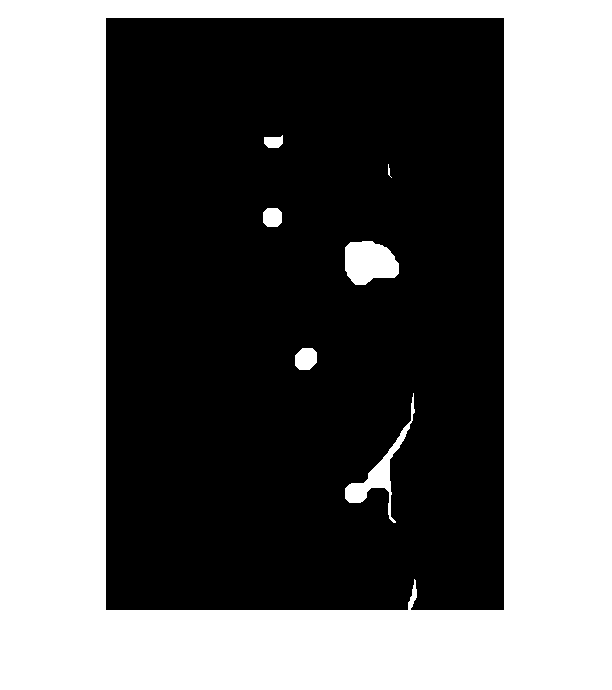



imshow(eye_mask);


mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)

[x,y] = mouth_index(mouth_mask)

x = 397

y = 186

[indexX,indexY] = eye_index(eye_mask)

indexX =   167.0000  168.1354  200.5000  263.9097


indexY =   200.0000  124.4844  341.5000  244.9260



% eye_centers = cat(length(indexX),x,y);
%----------------------------------------%
% Calculate the center of the mouth (you might need to adjust this based on your specific case)
mouth_center = [x, y]; % replace with actual coordinates

% Calculate the distance of each eye center from the mouth center
eye_centers = [indexX(:) + indexY(:)/2, indexY(:)];
distances = sqrt(sum((eye_centers - mouth_center).^2, 2));

% Find the indices of the two eyes with the closest distance to the mouth
%[~, sorted_indices] = sort(distances)
%closest_eye_indices = sorted_indices(1:2)
%closest_eyes = [indexX(closest_eye_indices), indexY(closest_eye_indices)]

% Beräkna avståndet mellan varje öga och ansiktets mitt
face_mid = [size(img, 2) / 2, size(img, 1) / 2]; % Mitt av ansiktet
eye_distances_to_mid = sqrt((indexX - face_mid(1)).^2 + (indexY - face_mid(2)).^2);

% Sortera ögonen baserat på avståndet till ansiktets mitt
[sorted_mid_distances, sorted_mid_indices] = sort(eye_distances_to_mid)

sorted_mid_distances =    45.5247   82.5943  101.1929  174.2706


sorted_mid_indices =      3     4     1     2



% Välj de två ögonen som är närmast ansiktets mitt
closest_mid_eye_indices = sorted_mid_indices(1:2)

closest_mid_eye_indices =      3     4


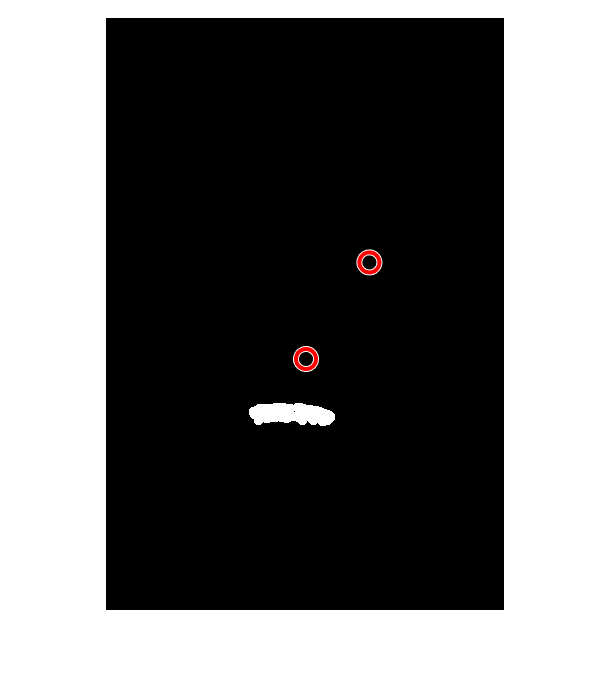

closest_mid_eyes = [indexX(closest_mid_eye_indices), indexY(closest_mid_eye_indices)];

%test

% Visualization
viscircles([closest_mid_eyes(1), closest_mid_eyes(3)], 10);
viscircles([closest_mid_eyes(2), closest_mid_eyes(4)], 10);

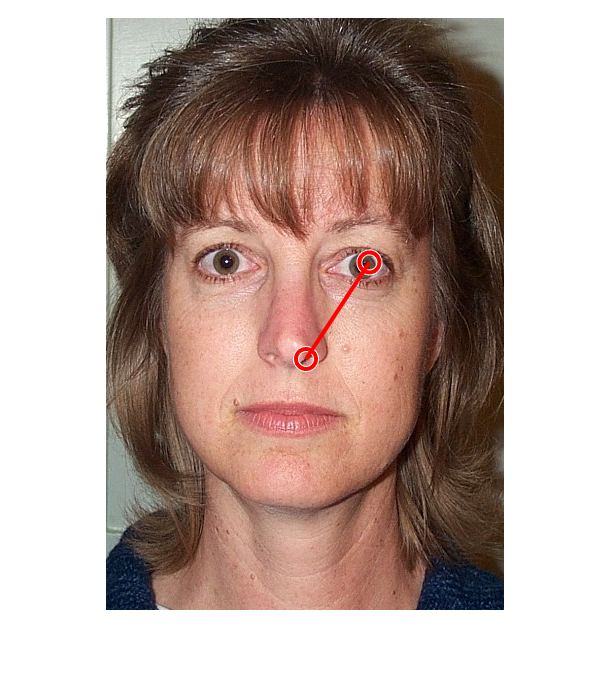


eye1 = [closest_mid_eyes(1), closest_mid_eyes(3)];
eye2 = [closest_mid_eyes(2), closest_mid_eyes(4)];


figure;
imshow(img);
hold on;
viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')

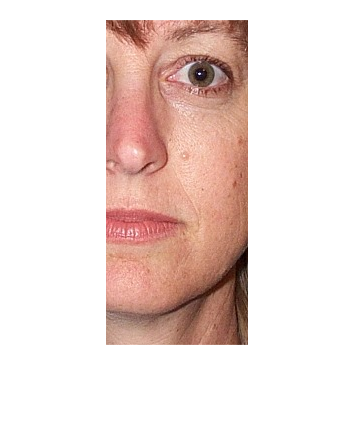


% Definiera antal pixlar från munnen neråt, ögonen uppåt, samt ögonen utåt
pixels_down_from_eyes = 180; % Antal pixlar från munnen neråt
pixels_up_from_eyes = 50;    % Antal pixlar från ögonen uppåt
pixels_sideways_from_eyes = 40; % Antal pixlar från ögonen utåt

% Beräkna koordinaterna för den nya rektangeln som inkluderar ansiktet
xmin = min([eye1(1), eye2(1)]) - pixels_sideways_from_eyes;
ymin = min([eye1(2), eye2(2)]) - pixels_up_from_eyes;
width = max([eye1(1), eye2(1)]) - xmin + pixels_sideways_from_eyes;
height = max([mouth(2), eye1(2), eye2(2)]) - ymin + pixels_down_from_eyes;

% Säkerställ att det inte går utanför bildens gränser
xmin = max(1, xmin);
ymin = max(1, ymin);
width = min(size(img, 2) - xmin + 1, width);
height = min(size(img, 1) - ymin + 1, height);

% Avrunda koordinaterna för att säkerställa att de är heltal
xmin = round(xmin);
ymin = round(ymin);
width = round(width);
height = round(height);

% Beskär bilden baserat på de beräknade koordinaterna
cropped_img = img(ymin:ymin+height-1, xmin:xmin+width-1, :);

% Visa den beskurna bilden
figure;
imshow(cropped_img)

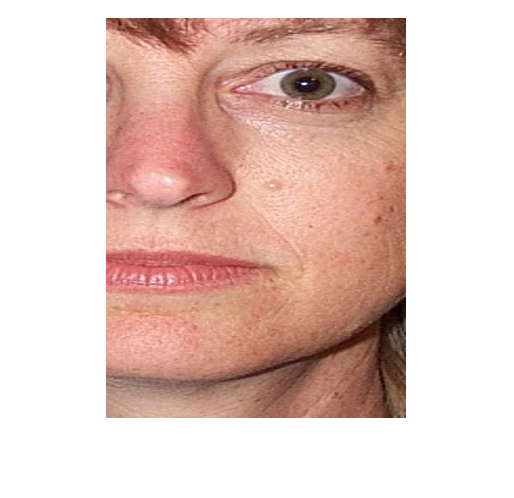


% Definiera önskad storlek för alla beskurna bilder
desired_height = 400;
desired_width = 300;

% Ändra storleken på den beskurna bilden till önskad storlek
resized_img = imresize(cropped_img, [desired_height, desired_width]);

% Visa den ändrade bilden till önskad storlek
figure;
imshow(resized_img);